## Load functions

% this file should be in the same directory as the /functions dir
% restoredefaultpath;
path = '~/Documents/Courses/Audio Signal Processing/Demo_FVN';
addpath([path '/matlab/functions']);

#### Load soundfile

addpath([path '/snd']);
[X, Fs] = audioread('pori.wav');

# Analysis/Synthesis parameters

% early/late separation
late_start  = 0.1;      % start time of late reverb analysis/sythesis [sec]
early_xfade = 0.1;      % crossfade time between early and late part of IR [sec]

% bandwidth rolloff analysis
lpOrder     = 10;       % Linear Prediction all-pole order for spectral estimation and H1 filter
rolloff_db  = -20;      % bandwidth rolloff threshold to track [dB]
segthresh   = 0.04;     % percentage of frequency decay to advance between segments
search_above = 750;     % ignore the spectral magnitudes below this frequency [Hz] (shrinks search space)
winsize     = 2048;     % "sliding" analysis window size [samples]
hopsize     = 500;      % analysis window hop, likely to determine min segment size [samples]
freqResolution = 2048;  % freqz resolution of LPC filter (number of points to generate for plots)

% velvet noise
vn_pwrSeq_dur = 1;      % duration of VN sequence to generate for measuring power [sec]
max_pfreq   = 250;      % max VN pulse freq
min_pfreq   = 40;       % min VN pulse freq
stretch     = 1;        % stretch factor for the synthesized IR

% coloration filters
fc_range    = [16000 8000]; % notch center freq range (first, last seg) [Hz]
fb_range    = [5000 4000]; % notch bw range (first, last seg) [Hz]
G_range     = [-6 -4];  % notch filter gain range [dB]
Hs_fc       = 20000;    % center freq of high shelf (center of skirt)
Hs_g        = -100;     % gain of high shelf

a_AP        = 0.7;      % all-pass coefficient
d_AP        = [ 225, 341, 441, 556 ]; % all-pass delays

late_mix_db = -31;      % mixing level of VN-RIR with early section
early_mix_db = -3;      % mixing level of early section

# Prepare for auto-segmentation; "sliding" analysis window

#### Divide IR into segments to analyze

start    = floor(late_start * Fs);
nwin     = floor(((length(X) - start) - (winsize-hopsize)) / (hopsize+1));
segments_an = zeros(winsize, nwin);

% collect the "sliding window" of samples
winStSamps = zeros(nwin, 1);
for i = 1:nwin
    st = start + (hopsize * (i-1));
    winStSamps(i) = st;
    segments_an(:, i) = getSamples(X, st, winsize);
end

clear st start nwin winsize hopsize

# Spectral estimate across the IR via Linear Prediction

[mags, mags_norm, lpfreqs, coeffs] = ...
    lpcData(segments_an, lpOrder, freqResolution, Fs);

### Analyse the frequency rolloff 

[rollidxs, rollfreqs, rollvals] = rolloffIdx( ...
    mags_norm, rolloff_db, search_above, Fs);

% clear rolloff_db search_above

# Find segment boundaries

frqHigh = rollfreqs(1);
frqLow  = 260;                  % found through inspection
freqstep = frqHigh * segthresh;
segStartIdxs = [winStSamps(1)];
cnt = 1;                        % analysis window counter
nextBoundaryFrq = frqHigh - freqstep;

while (nextBoundaryFrq >= frqLow) && (cnt <= length(rollidxs))
    thisfrq = rollfreqs(cnt);
    if (thisfrq < nextBoundaryFrq)
        % add this window's start frame to the segment boundary list
        segStartIdxs = [segStartIdxs winStSamps(cnt)];
        nextBoundaryFrq = nextBoundaryFrq - freqstep;
    end
    cnt = cnt+1;
end

if cnt == length(rollidxs)
    warning("reached the end of the analysis window list")
end
if nextBoundaryFrq < frqLow
    warning("*** next boundary fell below frqLow ***")
end

% initialize vars based on segment boundaries
seg_bounds = [segStartIdxs'; length(X)];     % segment boundaries, including endpoint
M = seg_bounds(2:end) - seg_bounds(1:end-1); % segment lengths
% nSeg = length(M);
nSeg = length(segStartIdxs);

clear cnt segthresh frqLow frqHigh nextBoundaryFrq thisfrq

# Analysis: Whiten IR Segments

### Retrieve segments

% IR segments
segments = {};

for i = 1:nSeg
    st = seg_bounds(i);
    len = M(i);
    %     segments{i} = X(st:st+len-1);
    segments{i} = getSamples(X, st, len);
end

seg_nsamp = seg_bounds(2:end) - seg_bounds(1:end-1);
% seg_nsamp(end) = seg_nsamp(end) + 1;

clear i M n st len

## Generate LPC whitening filters

whiten = true;  % analyse magnitudes of whitening filters (for plotting)

% storage
mags_lp   = zeros(freqResolution, nSeg);
freqs_lp  = zeros(freqResolution, nSeg);
coeffs_lp = zeros(lpOrder+1, nSeg);

for i = 1:nSeg
    [mags, ~, freqs, coeffs] = lpcData( ...
        segments{i}, lpOrder, freqResolution, Fs, whiten);
    mags_lp(:,i)    = mags;
    freqs_lp(:,i)   = freqs;
    coeffs_lp(:, i) = coeffs;
end

clear mags freqs coeffs i whiten

## Whiten the RIR segments, measure their power

segments_white = {};
for i = 1:nSeg
    segments_white{i} = filter(coeffs_lp(:, i), [1], segments{i});
end

% recompute spectrum estimate ... is it flat?
mags_lp_whitened  = zeros(freqResolution, nSeg);
freqs_lp_whitened = zeros(freqResolution, nSeg);
whiten = false; % calculate all-pole magnitudes, not as a whitening filter

for i = 1:nSeg
    [mags, ~, freqs, ~] = lpcData( ...
        segments_white{i}, lpOrder, freqResolution, Fs, whiten);
    mags_lp_whitened(:,i) = mags; % just keep the normalized spectrum
    freqs_lp_whitened(:,i) = freqs;
end

clear i whiten mag_resolution

### Set reference gain to signal power of WHITENED segments

% power_whitened = zeros(nSeg, 1);
% for i = 1:nSeg
%     power_whitened(i) = mean(segments_white{i}.^2);
% end
% 
% reference_gains = mag2db(power_whitened);
% % normalized to 0dB
% reference_gains_norm = reference_gains - max(reference_gains);

### OR: set reference gain to signal power of ORIGINAL segments

power_orig = zeros(nSeg, 1);

for i = 1:nSeg
    power_orig(i) = mean(segments{i}.^2);
end

reference_gains = mag2db(power_orig);
reference_gains_norm = reference_gains - max(reference_gains); % normalize to 0dB

# Velvet Noise Sequences

"*N*d = 100 pulses/s is sufficient in the very beginning of the late reverberation, where segments are very short, whereas *N*d = 40 pulses/s can be enough at the end where the bandwidth gets narrow. Between these extremes, the density is decreased linearly as a function of the segment index *m*." p. 7

#### Generate long sequences for gain matching

analysis_dur = round(vn_pwrSeq_dur * Fs); % duration of segments for gain analysis
vn_pfreqs = linspace(max_pfreq, min_pfreq, nSeg);
% matrix for long sequence
vn_seq_long = zeros(analysis_dur, nSeg);
% cell array for sequences to be used in the synthetic IR
vn_seq = {};

for i = 1:nSeg
    vn_seq_long(:, i) = velvet(analysis_dur, vn_pfreqs(i), Fs);
    if seg_nsamp(i) < Fs/vn_pfreqs(i) % if segment length is shorter than pulse period
        % make sure a pulse falls within the segment
        vn_seq{i} = velvet(seg_nsamp(i)*stretch, vn_pfreqs(i), Fs, true);
    else
        vn_seq{i} = velvet(seg_nsamp(i)*stretch, vn_pfreqs(i), Fs);
    end
end

clear min_pfreq max_pfreq vn_pfreqs stretch

# Coloration Filters

#### Generate the differential notch filters

H1A = coeffs_lp(:,1);
H1B = [1; zeros(lpOrder, 1)];
LP = true; % if true, add high shelf

[Adiff, Bdiff, Acolor, Bcolor] = genDiffFilters( ...
    H1A, H1B, nSeg, fc_range, fb_range, G_range, Fs, LP);

### Filter ("colorize") the long VN sequences

vn_seq_colored = zeros(analysis_dur, nSeg);

for i = 1:nSeg
    vn_seq_colored(:,i) = filter(Bcolor{i}, Acolor{i}, vn_seq_long(:,i));
end

### Whiten the colorized VN sequences (experimental)

for i = 1:nSeg
    vn_seq_colored_white{i} = filter( ...
        coeffs_lp(:, i), [1], vn_seq_colored(:,i));
end

# All-pass cascade

### Send colorized VN sequences through AP section prior to analysis

% choose later whitened or non-whitened to calculate segment gain
vn_seq_colored_ap = zeros(analysis_dur, nSeg);
vn_seq_colored_white_ap = zeros(analysis_dur, nSeg);

for i = 1:nSeg
    % note: rolloff_threshold is omitted, so returned signal is same size
    % as X. analysis should be done after the "warmup" period of the
    % response.
    vn_seq_colored_ap(:,i) = apCascade(vn_seq_colored(:,i), a_AP, d_AP);
    vn_seq_colored_white_ap(:,i) = apCascade(vn_seq_colored_white{i}, a_AP, d_AP);
end

## Calculate the power of the colored, all-passed VN

### CHOOSE which VN sequence to compare to RIR:  colorized+whitened, or just colorized

power_vn = zeros(nSeg, 1);
power_vn_white = zeros(nSeg, 1);

for i = 1:nSeg
    power_vn(i) = mean(vn_seq_colored_ap(:,i).^2);             % colorized sequences
    power_vn_white(i) = mean(vn_seq_colored_white_ap(:,i).^2); % colorized+whitened sequences
end

vn_seq_gains = mag2db(power_vn);                                  % convert to dB
vn_seq_gains_norm = vn_seq_gains - max(vn_seq_gains);             % normalized to 0 dB
vn_seq_gains_white = mag2db(power_vn_white);                      % convert to dB
vn_seq_gains_norm_white = vn_seq_gains - max(vn_seq_gains_white); % normalized to 0 dB

#### Calculate the makeup gain

makeup_gains = reference_gains_norm - vn_seq_gains;
% makeup_gains = reference_gains-vn_seq_gains;
% makeup_gains = makeup_gains-max(makeup_gains);

## Generate optional logarithmic decay curve

Optionally use this gain curve in place of curve from power analysis

stdb = 0;
enddb = -60;
n = nSeg;

log_decay = exp(linspace(log(db2mag(stdb)), log(db2mag(enddb)), n));

% plot(mag2db(log_decay))

clear stdb enddb n

# Putting it all together: VNC+Coloration+Gain

#### A tap is taken after each gain stage.

#### Define input signal

input = [1; zeros(2047, 1)];

#### **Calculate the output buffer size**

The buffer size of each stage is **size(input) + size(convKernel) - 1**

% outsize = length(input) + sum(seg_nsamp) - nSeg;
% outsize = outsize*10;             % streeeeetch it out
outsize = round(length(X) * 1.3);   % or just consider the length of the original and pad for SAP tail

#### Pack filter coeffs into one structure

colorFiltA{1} = H1A;
colorFiltB{1} = H1B;
for i = 1:nSeg-1
    colorFiltA{i+1} = Adiff(:,i);
    colorFiltB{i+1} = Bdiff(:,i);
end

## Generate output taps after Coloration & Gain

NOTE: possible manual gain modification

% output matrix holding network taps, pre-gain, pre-SAP
taps = zeros(outsize, nSeg);
prevseqlen = 0;

% loop through the cascade, segment by segment
for i = 1:nSeg
    % ~~~ filter input with coloration filter ~~~
    filtered = filter(colorFiltB{i}, colorFiltA{i}, input);
%     filtered = input; % uncomment to omit coloration
    
    % ~~~ convolve with VN sequence ~~~
    convolved = conv(filtered, vn_seq{i}); % for cascading convolution: INCORRECT
    
    convseq = [zeros(prevseqlen,1); vn_seq{i}];
    convolved = conv(filtered, convseq);
    
    % ~~~ zero-pad each output tap to fit in the tap matrix ~~~
    padlen = outsize-length(convolved);
    padded = [convolved; zeros(padlen,1)];
    
    % ~~~ apply gain term ~~~
    padded = padded * db2mag(makeup_gains(i)/2); % TODO: gain modification
    
    % store output from post-gain "taps"
    taps(:, i) = padded;
    
    % rotate variables for next iteration
%     input = convolved; % for cascading convolution: INCORRECT
    input = filtered;
    prevseqlen = prevseqlen+length(vn_seq{i});
end

summed_ir = sum(taps, 2);

clear padded convolved prevseqlen input

### TEST: cascaded VNCs

v1 = velvet(round(0.5*Fs), 200, Fs);
v2 = velvet(round(0.5*Fs), 150, Fs);
v3 = velvet(round(0.5*Fs), 100, Fs);
v4 = velvet(round(0.5*Fs), 80, Fs);
v5 = velvet(round(0.5*Fs), 60, Fs);

vc = conv(v1, v2);
vc = conv(vc, v3);
vc = conv(vc, v4);
vc = conv(vc, v5);

vnc_cascade = vc/max(vc);

# All-pass Cascade

"The delay line lengths of the SAP filters are 225, 341, 441, and 556 samples, and their filter coefficient is *a *= 0.7. " p.7

ap_out = summed_ir;

% NOTE: this will determine the length of the returned signal, based on 
% and energy decay tail cutoff point. Quite crude, as underlying
% calculation assumes low order filters...
rolloff_threshold = -50;

for del = d_AP
    ap_out = schrdAllpass(ap_out, a_AP, del, rolloff_threshold);
end

### First arrival / Early reflections

T = round(early_xfade * Fs);        % transition time to "crossfade" after 100ms
offset = round(late_start * Fs);   % duration of early response before fadeout
H = hanning(T*2);           % window function for fadeout
H = H(T+1:end);
env = [ones(offset, 1); H];

early = X(1:length(env)) .* env;    % window the early response
early = early / max(early);         % normalize to 0 dB

% plot(early); hold on;
% plot(env, '--r');
% hold off

### Mix in first arrival with VN-IR

By inspection, the late part peaks at -16 dB below the first arrival.

VN-IR is rendered normalized to -3 dB (confirm!).

Windowed early part is normalized ot 0dB.

So for an IR normalized to -3 dB, mix in early response at -3dB and late part at -16 db

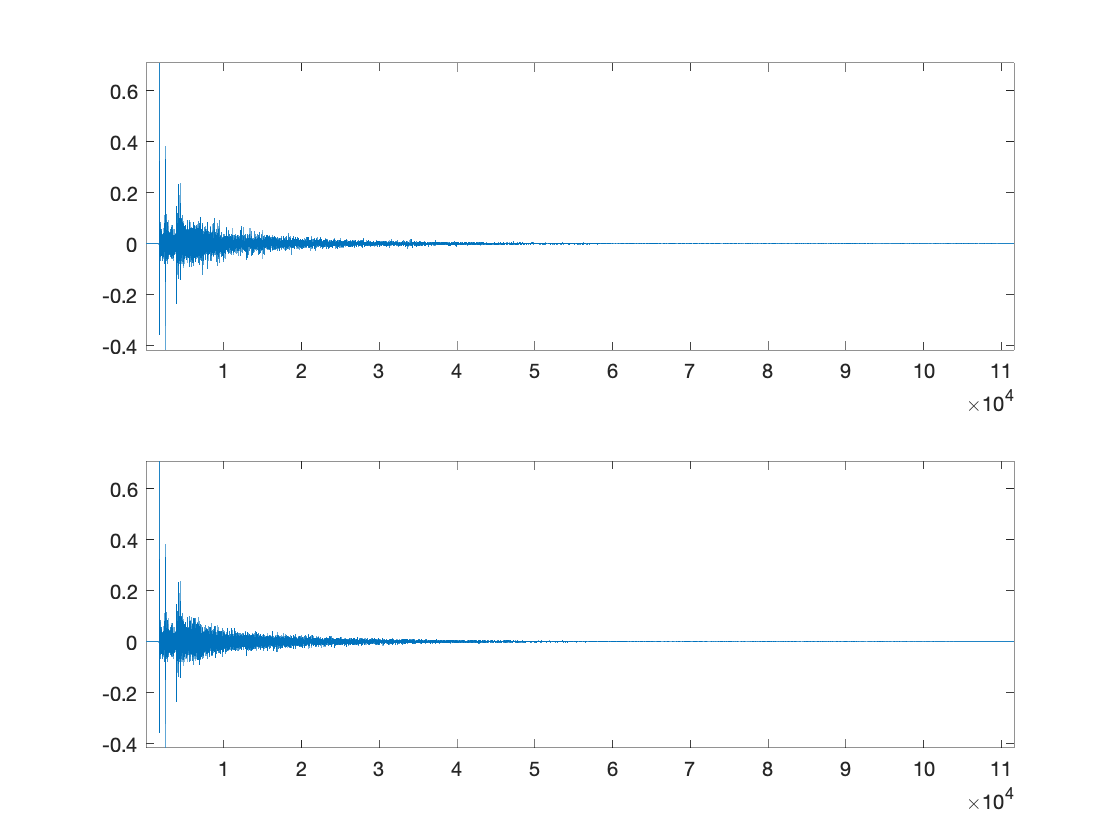

late_mix  = db2mag(late_mix_db);   % late part already normalized to -3 dB
early_mix = db2mag(early_mix_db);  % early part already normalized to 0 dB

ir_mixed = [zeros(offset,1); ap_out * late_mix];
mix_idxs = 1:offset+T;
ir_mixed(mix_idxs) = ir_mixed(mix_idxs) + early * early_mix;

% VN-IR
subplot(2, 1, 1)
plot(ir_mixed);             
xlim([1 length(X)])

% RIR
subplot(2, 1, 2)
plot(X/max(X)*db2mag(-3));  
xlim([1 length(X)])


% clear early_mix late_mix mix_idxs % keep for plotting